# Robotics I Mini-Project 5: Vision Guided Motion

clearvars
cd('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\FALL21Robotics\MiniProject5')
addpath(genpath('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\MATLABrelated\'))
addpath(genpath('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\FALL21Robotics\MiniProject5'))

## Part 1: Camera Model and Projective Geometry

In this part, we want to be able to recreate the image plane pictures of the 3d S-shaped curve using a simple pinhole camera model. 

First we create a pinhole camera object with the given parameters.

cam_def;

The camera object contains 10 intrinsic parameters:

 5 in the skew model $K = \left[ \matrix{f/\rho_w & \alpha f/ \rho_w & u_0 \cr 0 & f/\rho_h & v_0 \cr
0 & 0 & 1}\right]$,

5 in the calculation of true image pixel cordinate $\left[ \matrix{u_{true} \cr v_{true}} \right]$:

$\{k_1, k_2, k_3, k_4, k_5\}$.

Next we load our object "s-shaped path" from the previous project.

load S_sphere_path_uniform.mat pS

We use the origin of the path as $[x_0,y_0,z_0]$ and convert camara origin to the reference frame:

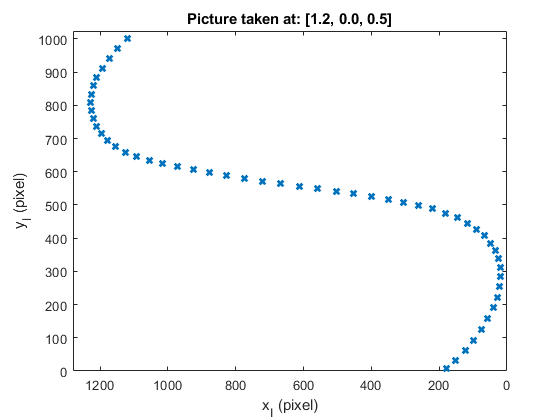

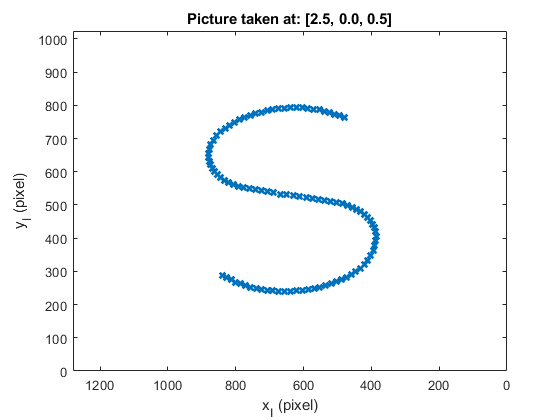

xc = [1.2,2.5];
for i = 1:2
poc = [xc(i);0;0.5];
R0C = [0, 0, -1;
       -1, 0, 0;
       0, 1, 0];
[uv,uvw,P1] = cam_image(cam,[R0C,poc;[0,0,0,1]],pS);
figure;plot(uv(1,:),uv(2,:),'x','LineWidth',2);
xlabel('x_I (pixel)')
ylabel('y_I (pixel)')
title(sprintf('Picture taken at: [%0.1f, %0.1f, %0.1f]',poc(1),poc(2),poc(3)))
axis([0,cam.uv0(1)*2,0,cam.uv0(2)*2])
set(gca,'xdir','reverse')
end

The above plotting method referenced Prof. Wen's Code displayed in Lecture 18.

## Part 2: Intrinsic Camera Parameter Calibration

In previous section, with camera parameter known, we are able to visulize what the camera is seeing with $p_{OC}$ given. In this part, we are given an unknown camera parameter, and the goal is to estimate the intrinsic parameters of the camera with a sets of know target points.

#### a) Derivation of Camera Calibration

First we decided that we will use Fix Camra / Moving Target appoach.

we first take $M 
$ number of pictures of a known pattern points array at random $[R_{OC},\; p_{OC}]$ pairs (note that $O$ is the corner/origin of the target frame, $C$ is the origin of the camera frame). 

The relationship between the target positions and their image projections can be modeled by $K$ using the following equation:


$$w_i \left[\matrix{u_i \cr v_i \cr 1}\right] = 
K \left[\matrix{ R_{CO} & p_{CO} } \right]\: \left[\matrix{p_{Oi} \cr 1} \right]$$


In his equation, $K$ is the intrinsic camera parameter that we discussed in part 1. As the target is planner, the $Z_i = 0$ in the target frame.

We then calculate the 2D homography matrix $H = K \left[\matrix{ R_{CO} & p_{CO} } \right]$ that map known points in target frame $(\beta_i)$ to pixels of the image in camera frame $(\alpha_i)$. This require us to reshape $H$ from a 3 by 3 square matrix to a 9 by 1 tall matrix. We can write all the known in $A_i \in \mathbb{R}^{3\times 9}$ where each image would generate a new $A_i, \quad i\in\{1,2,\cdots,M\}$ stacked under the previous one. 

To find an approximate $H \approx \mathcal{N}(A)$, we use $V$ from the smallest singular value of SVD. To extract K from H, we use the idea that rotation matrix has unit norm. This allow us to write out relationship between K and H as $L_mB = 0$ where $B = K^{-1^T}K^{-1} $ . While $H$ is in $L_m$, we use SVD again to approximate $B \approx \mathcal{N}(L_m)$.

Next we use Cholesky Decomposion to solve for $K$ from $B$.

#### b) how # targets points and number of views affect the estimate

Prof. Wen's target_def generates a square points array with edge length of 0.4. I modified the code a bit so it takes arguments that changes the # targets points inside the square points array. (noise $\sigma = 0.5
$)

**** Singular Values ****: [  6.206,  4.848,  0.3963,  0.0008672,  0.0002096,  2.186e-08  ]
K
   1.0e+03 *

    1.5000         0    0.6400
         0    1.5000    0.5120
         0         0    0.0010

Estimated K
   1.0e+03 *

    1.6082    0.0038    0.6785
         0    1.6098    0.5285
         0         0    0.0010

percentage error in K
 7.2, -, 6
 -, 7.3, 3.2
 -, -, 0



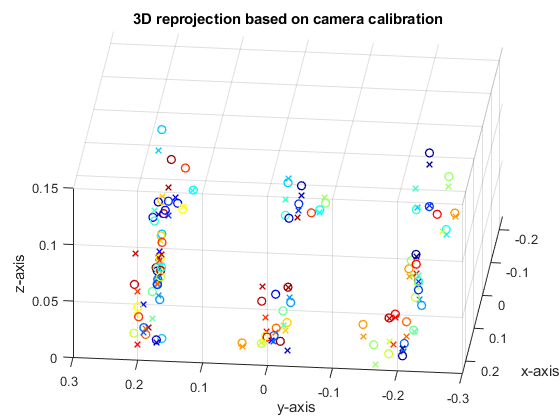

**** Maximum Reprojection Error:    0.925


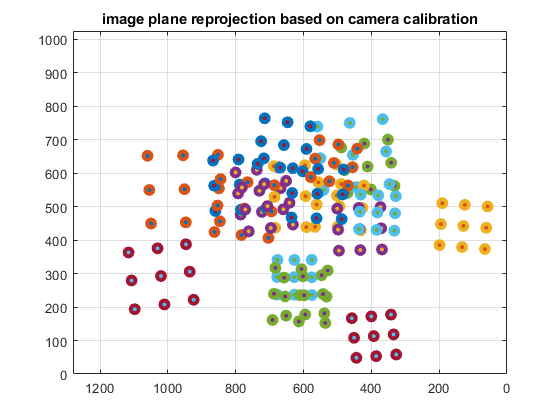

camcalib(20,5)

With 20 images generated and {3,5,7} points generated on the side:

$\%e_K(20,3)=
\left[\matrix{
7.6 &-&1.4 \cr
0&7.8&3.8\cr
-& - & 0
}\right]$, $\%e_K(20,5)=
\left[\matrix{
3 &-&5.6 \cr
0&3.1 &2.7\cr
-& - & 0
}\right]$, $\%e_K(20,9)=
\left[\matrix{
2.2 &-&0.24 \cr
0&2.2&1.1\cr
-& - & 0
}\right]$

It seems that more points slightly improve the percentage error in intrinsic parameter but the increased computation time overshadowed the improvement. 

More points significantly decrease the projection error (about 50% decrease from 3 points to 5 points).

some patterns are out of view
some patterns are out of view
some patterns are out of view
**** Singular Values ****: [  8.758,  6.632,  0.5213,  0.001066,  0.0002381,  2.039e-08  ]
K
   1.0e+03 *

    1.5000         0    0.6400
         0    1.5000    0.5120
         0         0    0.0010

Estimated K
   1.0e+03 *

    1.4972   -0.0020    0.6510
         0    1.4977    0.5057
         0         0    0.0010

percentage error in K
 0.19, -, 1.7
 -, 0.16, 1.2
 -, -, 0



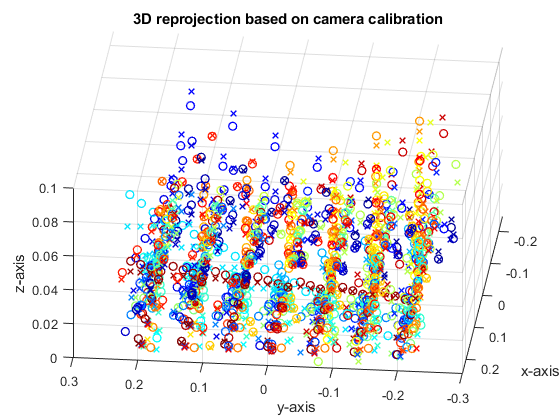

**** Maximum Reprojection Error:    0.56


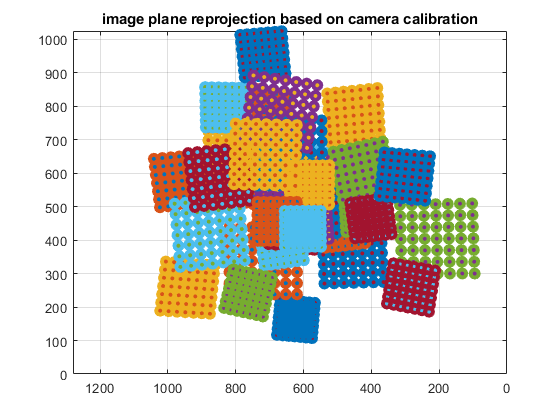

camcalib(40,7)

$\%e_K(3,5)=
\left[\matrix{
28 &-&8.5 \cr
0&28&12\cr
-& - & 0
}\right]$, $\%e_K(20,5)=
\left[\matrix{
3 &-&5.6 \cr
0&3.1 &2.7\cr
-& - & 0
}\right]$, $\%e_K(40,5)=
\left[\matrix{
2.8 &-&1.2 \cr
0&2.7&2.3\cr
-& - & 0
}\right]$

It seems that more images taken improve the overall percentage errors, specifically errors on [$u_0$ $v_0$]. However, it also at the same time increase the projection error.

#### 3) Find #points and #images so that error is with in 1%, reprojection error less than 1 pixel

with Gaussian noise centered at 0, $\sigma = 0.1$

some patterns are out of view
some patterns are out of view
**** Singular Values ****: [  6.389,  4.947,  0.3846,  0.0007043,  0.0001131,  3.176e-09  ]
K
   1.0e+03 *

    1.5000         0    0.6400
         0    1.5000    0.5120
         0         0    0.0010

Estimated K
   1.0e+03 *

    1.4910    0.0004    0.6415
         0    1.4906    0.5140
         0         0    0.0010

percentage error in K
 0.6, -, 0.23
 -, 0.63, 0.38
 -, -, 0



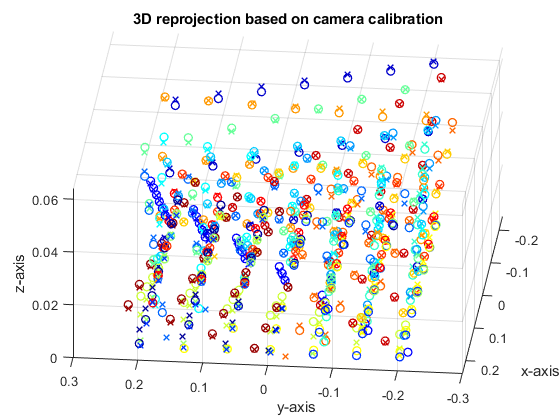

**** Maximum Reprojection Error:    0.149


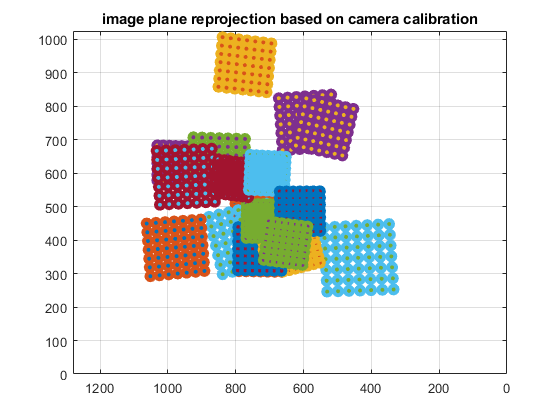

camcalib(20,7)

With 20 pictures and 7 points, the error was within the requirement 9/10 times. 

## Part 3: Camera/Robot Calibration

*This part uses Prof. Wen's hand_eye_cal.m

Now supposed that we mount the calibrated camera on top of a robot who base location was not precisely known. With a very good estimate of $K$, we can solve for the distance between the camera and the target by taking at lease 3 pictures of a planer target (used in the previous part to evaluate projection error) or 6 pictures of a 3D target. 


$$w_i \left[\matrix{u_i \cr v_i \cr 1}\right] = 
K \left[\matrix{ R_{CO} & p_{CO} } \right]\: \left[\matrix{p_{Oi} \cr 1} \right]$$


In our s-shaped curve, the 101 points has depth information, therefore we solved a general PnP problem to obtain $T_{CO}$ and from that we then obtained $T_{BO} \text{ and } T_{CT}$.

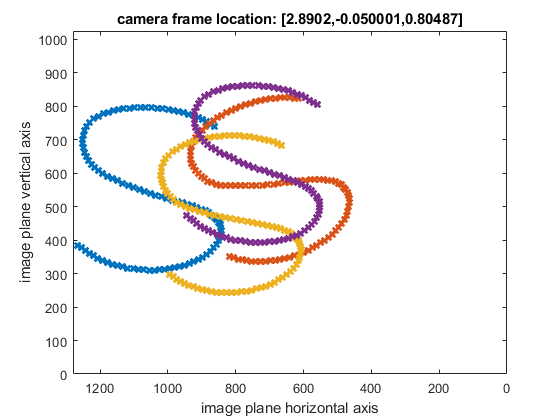

p_TC vs. estimate
         0    0.0063
         0   -0.0022
    0.0500    0.0519

p_0B vs. estimate
    2.5000    2.5056
         0   -0.0029
         0   -0.0013



addpath(genpath('C:\Users\kongc\Dropbox\RPI_2021FALL\RoboticsI\FALL21Robotics\MiniProject4'))
hand_eye_cal

## Part 4: Visual Servioing

*Code was provided by Prof. Wen then parsed by sections to reflect understanding.

From provious two sections, we obtained an estimated camera intrinsic parameter $K$ from points grid. With camera mounted somewhere on the end effector of the robot, we can find the distance between the camera and the target frame by again, taking some photos of the target. Using $K$ we can solve for either planer or general PnP problem that provide us with the location of the camera $T_{OC}$ in the target frame.

The goal of this part is to use the previously obtained camera / robot intrinsic and extrinsic parameters to drive the robot arm to the desired pose. 

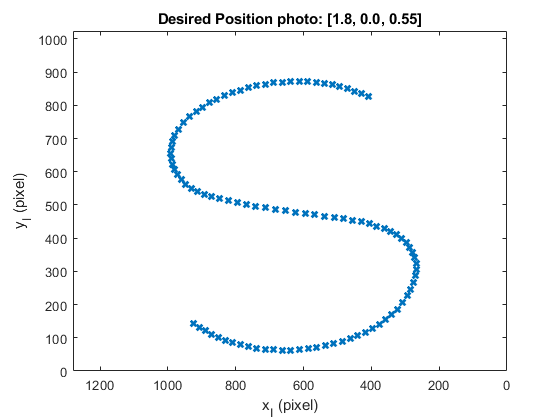

poc = [1.8;0;0.55];
R0C = [0, 0, -1;
       -1, 0, 0;
       0, 1, 0];
Toc = [R0C,poc;[0,0,0,1]];
[uv,uvw,P1] = cam_image(cam,Toc,pS);
figure;plot(uv(1,:),uv(2,:),'x','LineWidth',2);
xlabel('x_I (pixel)')
ylabel('y_I (pixel)')
title(sprintf('Desired Position photo: [%0.1f, %0.1f, %0.2f]',poc(1),poc(2),poc(3)))
axis([0,cam.uv0(1)*2,0,cam.uv0(2)*2])
set(gca,'xdir','reverse')

#### a) Position Based Visual Servoing (PBVS)

In real world practice, we first take a picture to calculate the desired pose $T_{BT}$ from $p_I$:


$$T_{BTdesire} = T_{BO}T_{OC}T_{CT}$$


where $T_{BO}$ and $T_{CT}$ was estimated from hand-eye-calibration. 

In this case we know our desired pose to be:

T_BT_des=inv(T_0B_est)*Toc*inv(T_TC_est);
disp(T_BT_des)

   -1.0000         0         0   -0.6994
         0   -1.0000         0   -0.0008
         0         0    1.0000    0.5006
         0         0         0    1.0000



Next we will be doing something very similar to iterative inverse kinematics with gradient discent except that $e_{R_T} = R_{BT(est)}\:R_{BT(des)}^T$, and $e_{p_T} = p_{BT(est)} - p_{BT(des)}$ , we then use the Jacobian of the robot we obtained from MiniProject 4 to find the next joint angle $q$. Notice that one has to use the forward kinamatics function to find the next $T_{BT} \rightarrow T_{OC}$ to take the next image. 

rb1200.q=[0.1;1.6;3.5;3;2;0];
N=30;
irb1200.MaxIter=N; % # of iteration for kinematic control
irb1200.StepSize=.3;   % controller gain
irb1200.Weights=[1;1;1;10;10;10]; % weighting factors
T_0C_des = Toc

T_0C_des =          0         0   -1.0000    1.8000
   -1.0000         0         0         0
         0    1.0000         0    0.5500
         0         0         0    1.0000


[q,uv,T_0C]=PBVS_unlimited_range(irb1200,cam,pS,T_0C_des,T_0B,T_TC,T_0B_est,T_TC_est);

image out of range
image out of range
image out of range
image out of range


disp(T_0C{N+1})

    0.0025   -0.0020   -1.0000    1.8000
   -1.0000    0.0032   -0.0025    0.0002
    0.0032    1.0000   -0.0020    0.5501
         0         0         0    1.0000



disp(T_0C_des)

         0         0   -1.0000    1.8000
   -1.0000         0         0         0
         0    1.0000         0    0.5500
         0         0         0    1.0000



Visualizing the result in Live Editor with "movie" was limited, but we can see that the final estimated $T_{OC}$ was quite accurate.

#### b) Image-based Visual Servoing (IBVS)

The key difference between IBVS and PBVS, is that in IBVS, camera's intrinsic parameter $K$ become part of the Jacobian matrix. In otherword, instead of correcting for the change of the end effector pose, we correct the joint angle with change of the image, so instead of :


$$\left[ \matrix{\omega_T \cr v_T} \right] = 
J_T \: \dot{q}, \quad J_T\in\mathbb{R}^{6 \times 6}$$


The image Jacobian convert joint angle changes to the pixel positon changes:


$$\left[ \matrix{\dot{u}\cr \dot{v}} \right] = 
J_I \: \dot{q}, \quad J_I\in \mathbb{R}^{202 \times 6}$$


One can analytically solve for $J_I$ but we can also use forward difference to estimate the change of $u$ and $v$. We do that by applying perturbation $\epsilon = 0.1$ on $q$ to estimate for the gradient of the least square problem:

 
$$\min_{\dot{q}} \left|\left| J_I \:\dot{q} - \left( - K_p \left[ \matrix{u - u^* \cr v - v^*}\right] \right)\right|\right|$$


In this set up, $K_p = 0.03$ is the step size of each correction based on the estimated pixel changing speed from $J_I$. 

load targetS_part4
uv_des=uv;

% set up IBVS call
N=200;
irb1200.MaxIter=N; % # of iteration for kinematic control
irb1200.StepSize=.03;   % controller gain

% target camera frame with respect to reference frame 0
T_0C_des=[-ey ez -ex [1.8;0;0.55];0 0 0 1];
% PBVS to reduce error
%[q,uv,T_0C]=IBVS(irb1200,cam,pS,uv_des,T_0B,T_TC,T_0B_est,T_TC_est);
[q,uv,T_0C,JI,J,erruv]=IBVS_unlimited_range(irb1200,cam,pS,uv_des,T_0B,T_TC,T_0B_est,T_TC_est);

image out of range
image out of range
image out of range
image out of range



disp(T_0C{N+1})

    0.0004   -0.0007   -1.0000    1.8023
   -1.0000    0.0011   -0.0004   -0.0001
    0.0011    1.0000   -0.0007    0.5500
         0         0         0    1.0000



disp(T_0C_des)

         0         0   -1.0000    1.8000
   -1.0000         0         0         0
         0    1.0000         0    0.5500
         0         0         0    1.0000



From the result we can see that the camera was very close to the desired postion and orientation.

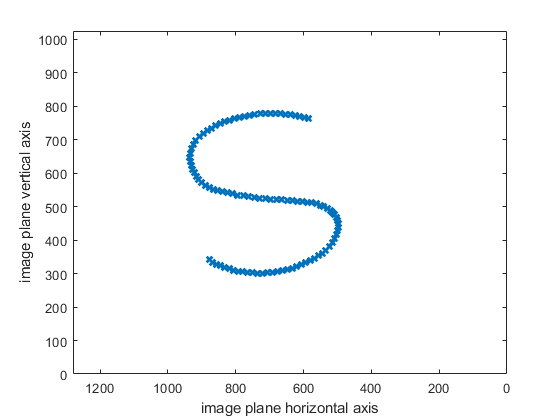

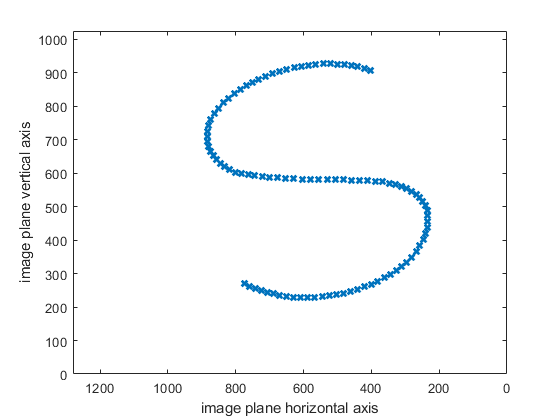

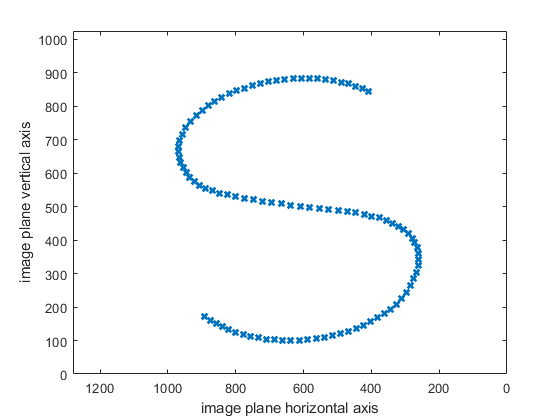

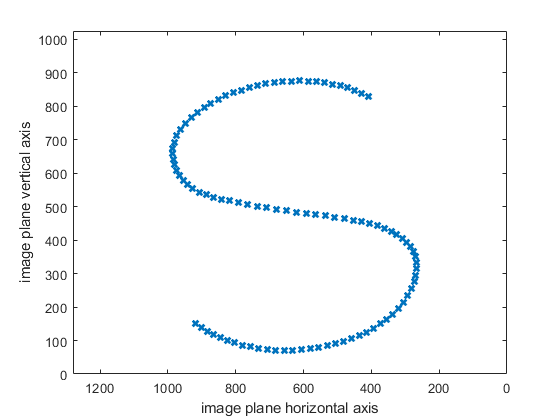

for i = 1:50:200
figure
plot(uv{i}(1,:),uv{i}(2,:),'x','linewidth',2);
 xlabel('image plane horizontal axis');
    ylabel('image plane vertical axis'); 
    axis([0 cam.uv0(1)*2 0 cam.uv0(2)*2]);
    set ( gca, 'xdir', 'reverse' );%pause
end

From the snip shots taken during the iteration, we can further confirm the convergence. 

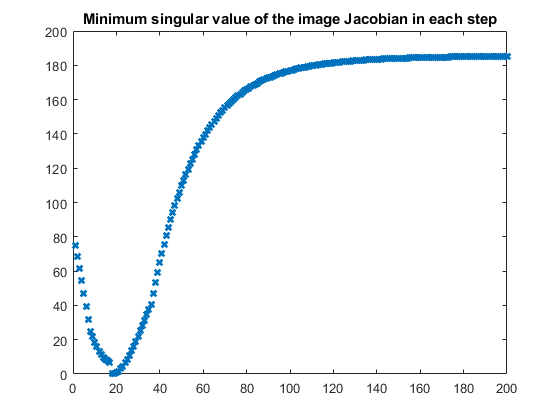

for i=1:irb1200.MaxIter;minJI(i)=min(svd(JI{i}));minJ(i)=min(svd(J{i}));end
figure(61);plot((1:irb1200.MaxIter),minJI,'x','linewidth',2);
title('Minimum singular value of the image Jacobian in each step');

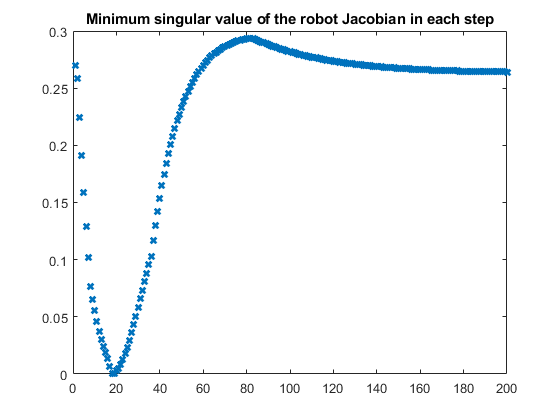

figure(62);plot((1:irb1200.MaxIter),minJ,'x','linewidth',2);
title('Minimum singular value of the robot Jacobian in each step');

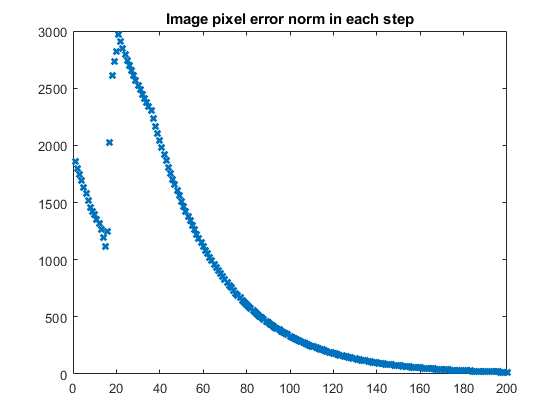

figure(63);plot((1:irb1200.MaxIter),vecnorm(erruv),'x','LineWidth',2);
title('Image pixel error norm in each step');

In the singularity analysis, we can see from the minimum singular value plots that the damage from the robot arm singularty propagated to the IBVS pixel error. However in Prof. Wen's code, the random perturbation of the angles at near singular positions helped assuaged the deadlock. 

## Conclusion:

In this project, two major topics covered was the representation of a simple pin-hole camera model, and the usage of camera in robot arm servoing. The key of a camera model is its intrinsic parameter $K$ and other parameters can be calculated after this. In the section of robot servoing, we saw two different ways of using pixel informations, and how we can link back to the Jacobian based inverse kinematics from Miniproject 4. In our example, PBVS seems to have a better overall performance than IBVS, this might partially comes from the additional least square problems added to the iteration. 